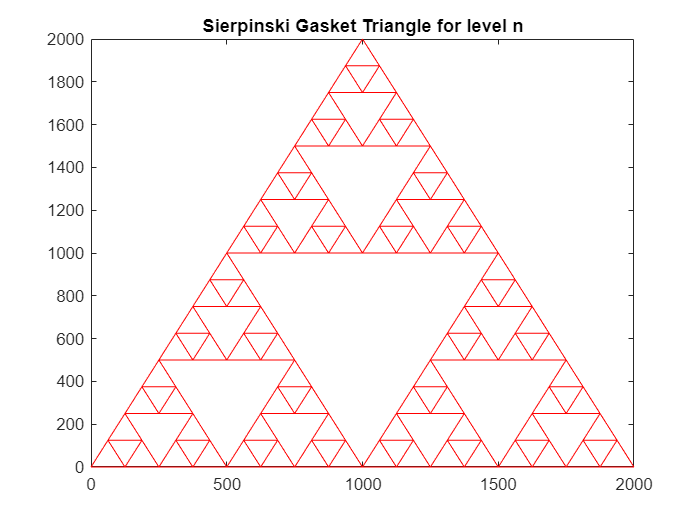

% 'm' (line 7) is the outter level SGT and 'n' (line 6) is the inner level SGT.
% Input: m,n are non-zero positive integers; m < n
% Output: Euler-Maruyama graph for the combination of m and n

l = []; %an arbitary matrix used to store the nodes in draw_n and draw_m functions
n = 4; %inner level
m = 2; % outter level
left_node = [0 0]; %starting cordinates of left node
top_node = [1000 2000]; %starting cordinates of top node
right_node = [2000 0]; %starting cordinates of right node

nodes_n = draw_n(n+1,left_node, top_node,right_node,l); %drawing SGT for level n matrix and finding its nodes
hold off


nodes_n = unique(nodes_n,'rows','stable') %removing the cordinates of the repeated nodes in level n

nodes_n = 1.0e+03 *

         0         0
    0.0625    0.1250
    0.1250         0
    0.1250    0.2500
    0.1875    0.1250
    0.2500         0
    0.1875    0.3750
    0.2500    0.2500
    0.2500    0.5000
    0.3125    0.3750



vertices_triangles_m = draw(m+1,left_node, top_node,right_node,l) %drawing SGT for level m matrix and finding its nodes(vertices)

vertices_triangles_m =            0         500         500           0
         250         750        1000         500
         500        1000         500           0
         500        1000        1500        1000
         750        1250        2000        1500
        1000        1500        1500        1000
        1000        1500         500           0
        1250        1750        1000         500
        1500        2000         500           0


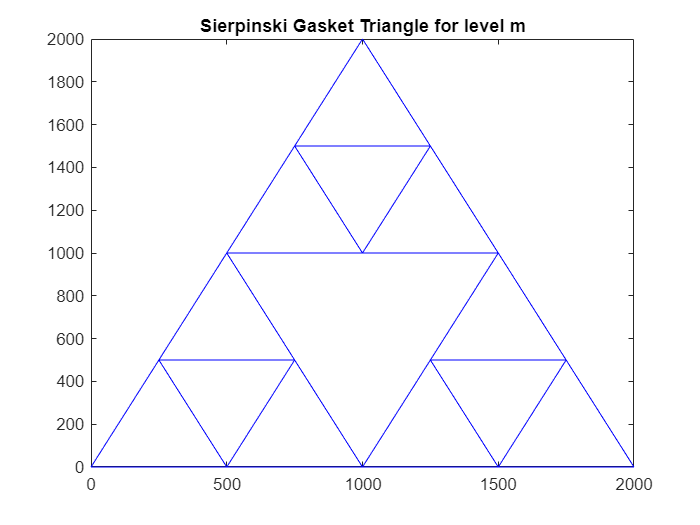

hold off


adjacency_matrix = adjacency(nodes_n,vertices_triangles_m) %function creates the adjacency matrix for the outer level m and inner level n

adjacency_matrix =      0     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     0     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     0     1     1     1     1     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     1     0     1     1     1     1     1     1     1     1     1


U_t_0 = sum(adjacency_matrix == 1) % number of neighbouring nodes for each node, calculated using adjacency matrix

U_t_0 =     14    14    14    14    14    14    14    14    28    14    14    14    14    14    28    14    14    14    14    14    14    14    28    14    14    14    14    14    28    14    14    14    14    14    14    14    14    14    14    14    14    28    14    14    14    14    14    14    14    28



L = L_mat(U_t_0,adjacency_matrix) % Calculates the Laplacian Matrix

L =    -14     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1   -14     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     1   -14     1     1     1     1     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     1   -14     1     1     1     1     1     1     1     1     1     1     1   

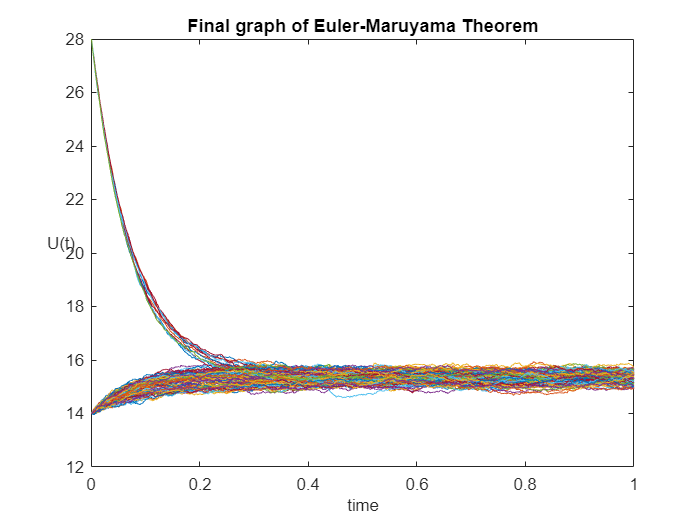


Euler_Maruyama(U_t_0.',L) %creates the Euler-Maruyama Graph

## L Matrix

% Calculates the Laplacian Matrix = Degree Matrix - Adjacency Matrix
% input: a matrix with the number of adjacent nodes for each node,
% adjacency matrix
% output: Laplacian Matrix


function L = L_mat(degrees,A)
D = zeros(length(A));

%for loop is used to make the diagonal degree matrix using the number of
%neighbouring nodes for each node
for i = 1 : length(A)
    D(i,i) = degrees(i);
end

L = A - D; % Laplacian Matrix = Degree Matrix - Adjacency Matrix
end

## The Euler–Maruyama Method

% function creates the Euler-Maruyama graph for the given degree matrix and
% Laplacian matrix
% input: degree matrix, Laplacian matrix
% output: Euler-Maruyama graph

function Euler_Maruyama = Euler_Maruyama(U_t,A)
randn('state',100) % set the state of randn
T = 1; % time considered is 1 second
N = 1000; % number of time divisions
dt = T/N; % time of each time division
U_prev = U_t;
k = 0.5; % constant
sigma = 0.5; % constant
draw = U_t; % the column matrix, which will be updated after after each increment
len = size(U_t);

% for loop finds the new column
for j = 2:N
    rn =  randn(len(1),1);
    dU = sqrt(dt)*rn;         % general increment
    U = U_prev + A.*k*U_prev*dt + sigma*dU;
    U_prev = U;
    draw = [draw,U];
end

% following lines plot the Euler-Maruyama
for i = 1 : size(draw,1)
    plot([T/N:dt:T],draw(i,:))       % plot W against t
    xlabel('time','FontSize',10)
    ylabel('U(t)','FontSize',10,'Rotation',0)
    title("Final graph of Euler-Maruyama Theorem")
    hold on
end
hold off
end

## Adjacency Matrix

% IMPORTANT: Adjacency matrix is symmetric on either side of the diagonal
% and the diagonal elements are always 0 because each node is not connected
% to itself
%input: cordinates of the unique nodes in level n and cordinates (vertices)
%of the unique nodes at level m
%output: adjacenecy matrix

function adjacency_matrix = adjacency(nodes, vertices)
len = length(nodes); %defining the number of nodes as the adjacency matrix will have dimensions of len x len
M = zeros(len); % making a square matrix of zeros dimensions of len x len
for i = 1 : len %looping on the rows
    M(i,i) = 0; %each node isn't connected to itself, hence no relationship; '0'
    for j = i + 1 : len %looping on the columns, except for (i,i)
        for k = 1 : length(vertices(:,1))
            x = [vertices(k,1) vertices(k,2) vertices(k,1)/2+vertices(k,2)/2];
            y = [vertices(k,4) vertices(k,4) vertices(k,3)];
            [in1,on1]=inpolygon(nodes(i,1),nodes(i,2) ,x, y); % makes a triangular polygon
            if in1 == 1 || on1 == 1 % checks if node 1 is in the polygon
                [in2,on2]=inpolygon(nodes(j,1),nodes(j,2) ,x, y);
                if in2 == 1 || on2 == 1 % checks if node 2 is in the polygon
                    % if both nodes are in the polygon then '1' is
                    % added to the adjacency matrix to the position
                    % (i,j)
                    M(i,j) = 1;
                    M(j,i) = 1;
                end
            end
        end
    end
end
adjacency_matrix = M; %returns adjacency matrix
end

## Draw SGT for n

%draws the adjacency matrix for level n and returns all the nodes of level
%n
%this is a recursive funtion
%input: level n, left node, top node, right node and empty list
%ouput: graph of SGT and node matrix for n

function e = draw_n(n,left_node, top_node,right_node,l)
if n == 1 %if the level is 1, it is the lowest level
    x = [left_node(1),top_node(1),right_node(1),left_node(1)];
    y = [left_node(2),top_node(2),right_node(2),left_node(2)];
    plot(x,y,"r-") % plots the triangle
    title("Sierpinski Gasket Triangle for level n")
    %upates the matrix l with the new nodes
    l = [l;left_node];
    l = [l;top_node];
    l = [l;right_node];
    hold on
else %if not at the lowest level, find the nodes of the inner triangle
    % when searching for the inner triangle, new nodes have to be found
    left_top_mid = midpoint(left_node,top_node);
    top_right_mid = midpoint(top_node, right_node);
    left_right_mid = midpoint(left_node, right_node);

    l=draw_n(n - 1,left_node,left_top_mid,left_right_mid ,l);
    l=draw_n(n - 1,left_top_mid,top_node,top_right_mid,l);
    l=draw_n(n - 1,left_right_mid, top_right_mid,right_node,l);
end
e = l; %retunrs the list with node cordinates
end

## Midpoint

%finds the midpoint of two given points
%input: point1, point2
%output: midpoint of x and y cordinates

function point = midpoint(point1,point2)
x = (point1(1)+point2(1))/2;
y = (point1(2)+point2(2))/2;
point = [x,y];
end

## Draw SGT for m

%draws the adjacency matrix for level m and returns all the nodes(vertices) of level
%m
%this is a recursive funtion
%input: level m, left node, top node, right node and empty list
%ouput: graph of SGT and node matrix for m

function e = draw(n,left_node, top_node,right_node,l)
if n == 1
    x = [left_node(1),top_node(1),right_node(1),left_node(1)];
    y = [left_node(2),top_node(2),right_node(2),left_node(2)];
    m = [left_node(1) right_node(1) top_node(2) right_node(2)];
    plot(x,y,"b-")
    title("Sierpinski Gasket Triangle for level m")
    %upates the matrix l with the new nodes
    l = [l;m];
    hold on
else %if not at the lowest level, find the nodes of the inner triangle
    % when searching for the inner triangle, new nodes have to be found
    left_top_mid = midpoint(left_node,top_node);
    top_right_mid = midpoint(top_node, right_node);
    left_right_mid = midpoint(left_node, right_node);

    l=draw(n - 1,left_node,left_top_mid,left_right_mid ,l);
    l=draw(n - 1,left_top_mid,top_node,top_right_mid,l);
    l=draw(n - 1,left_right_mid, top_right_mid,right_node,l);
end
e = l; %retunrs the list with node cordinates
end